%loading in mystery signal
data = load("Data_5_P(1).txt");

% view the size of data 
size(data)% 50000 row vs 3 columns

ans =        50000           3


data

data =          0   -0.0014         0
    0.0001   -0.0011         0
    0.0002    0.0015         0
    0.0003   -0.0039         0
    0.0004    0.0021         0
    0.0005   -0.0022         0
    0.0006   -0.0005         0
    0.0007    0.0016         0
    0.0008   -0.0031         0
    0.0009    0.0023         0



% This command allows to view the second column as data
data = data(:,2)

data =    -0.0014
   -0.0011
    0.0015
   -0.0039
    0.0021
   -0.0022
   -0.0005
    0.0016
   -0.0031
    0.0023


size(data) %50000 rows vs 1 column

ans =        50000           1


data

data =    -0.0014
   -0.0011
    0.0015
   -0.0039
    0.0021
   -0.0022
   -0.0005
    0.0016
   -0.0031
    0.0023



%declare N(length)
fs = 20000

fs = 20000

fc = fs/2

fc = 10000

N = 1000;
low = .4;
bnd = [.6 .9];

%fast fouier transform
s = fft(data);
%only view the first portion of the signal





high pass fir filter


q = fir1(N, [.5 .99], 'high', hamming(N+1))

q =     0.0000    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0001    0.0001   -0.0001   -0.0000   -0.0001    0.0001   -0.0001   -0.0000   -0.0001    0.0001   -0.0001   -0.0000   -0.0001    0.0001   -0.0001   -0.0000   -0.0001    0.0001


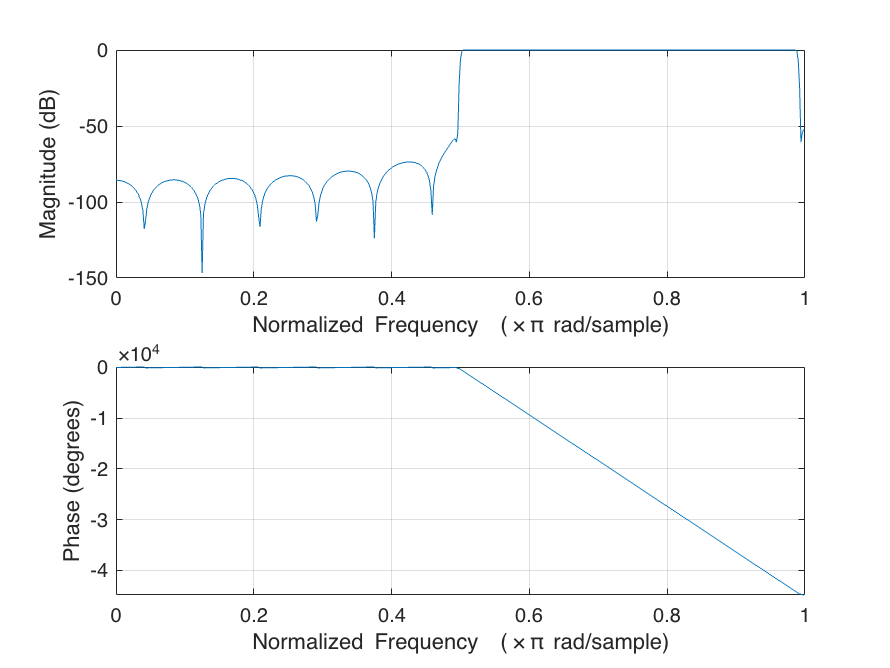

freqz(q, 1, 512)

low pass fir filter


%create an the fir filter with a cutoff of .1 - .9
h = fir1(N, [.1 .33], 'low', hamming(N+1))

h =    -0.0000   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0001    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0000    0.0000   -0.0000   -0.0001


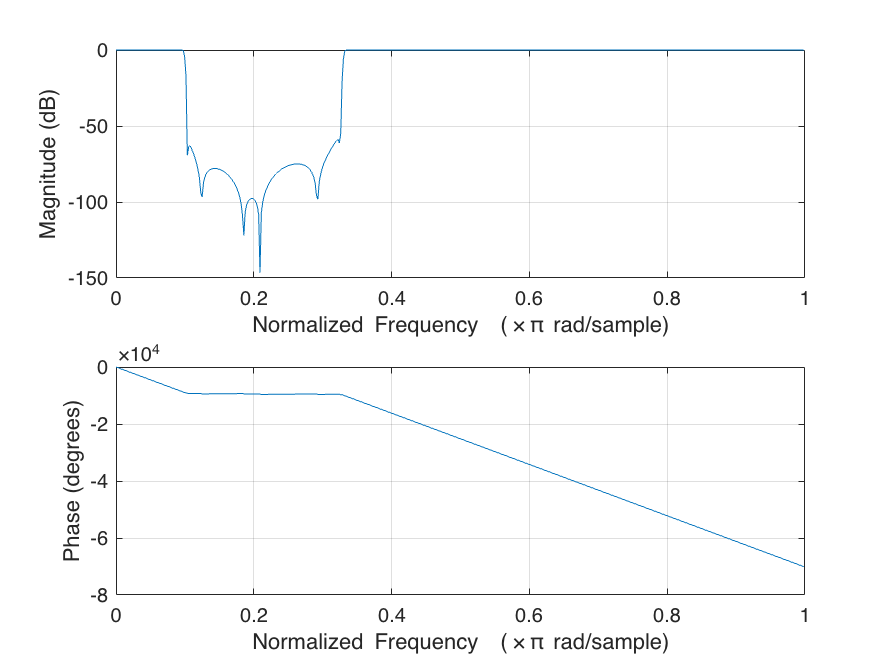

freqz(h, 1, 512)

FIR bandpass filter


% user created
p = fir1(120,[.35 .43], "stop");
freqz(p,1,512)

pf = fft(p)

pf =    1.0000 + 0.0000i  -0.9970 - 0.0259i   0.9987 + 0.0519i  -0.9943 - 0.0776i   0.9946 + 0.1037i  -0.9889 - 0.1291i   0.9880 + 0.1552i  -0.9808 - 0.1802i   0.9787 + 0.2063i  -0.9700 - 0.2309i   0.9667 + 0.2568i  -0.9566 - 0.2809i   0.9523 + 0.3067i  -0.9405 - 0.3301i   0.9353 + 0.3558i  -0.9219 - 0.3784i   0.9158 + 0.4039i  -0.9008 - 0.4256i   0.8934 + 0.4509i  -0.8798 - 0.4730i   0.8289 + 0.4738i  -0.5050 - 0.3063i   0.1079 + 0.0693i   0.0018 + 0.0012i  -0.0020 - 0.0015i  -0.0613 - 0.0465i   0.3830 + 0.3066i  -0.7001 - 0.5909i   0.7472 + 0.6647i  -0.7297 - 0.6838i   0.7096 + 0.7004i  -0.6933 - 0.7209i   0.6724 + 0.7365i  -0.6548 - 0.7556i   0.6335 + 0.7706i  -0.6145 - 0.7884i   0.5928 + 0.8026i  -0.5726 - 0.8191i   0.5504 + 0.8325i  -0.5293 - 0.8476i   0.5065 + 0.8600i  -0.4845 - 0.8738i   0.4612 + 0.8852i  -0.4385 - 0.8977i   0.4147 + 0.9081i  -0.3913 - 0.9192i   0.3670 + 0.9284i  -0.3430 - 0.9382i   0.3184 + 0.9463i  -0.2938 - 0.9547i


hf = fft(h)

hf =    1.0000 + 0.0000i  -1.0008 - 0.0031i   1.0000 + 0.0063i  -1.0008 - 0.0094i   0.9999 + 0.0126i  -1.0007 - 0.0157i   0.9998 + 0.0188i  -1.0006 - 0.0220i   0.9997 + 0.0251i  -1.0004 - 0.0283i   0.9995 + 0.0314i  -1.0002 - 0.0345i   0.9993 + 0.0377i  -1.0000 - 0.0408i   0.9990 + 0.0439i  -0.9997 - 0.0471i   0.9987 + 0.0502i  -0.9994 - 0.0534i   0.9984 + 0.0565i  -0.9991 - 0.0596i   0.9980 + 0.0627i  -0.9987 - 0.0659i   0.9975 + 0.0690i  -0.9983 - 0.0722i   0.9971 + 0.0752i  -0.9978 - 0.0785i   0.9966 + 0.0815i  -0.9974 - 0.0847i   0.9960 + 0.0878i  -0.9968 - 0.0910i   0.9954 + 0.0940i  -0.9963 - 0.0972i   0.9947 + 0.1002i  -0.9957 - 0.1035i   0.9940 + 0.1065i  -0.9951 - 0.1097i   0.9933 + 0.1127i  -0.9944 - 0.1160i   0.9925 + 0.1189i  -0.9938 - 0.1223i   0.9916 + 0.1251i  -0.9931 - 0.1285i   0.9906 + 0.1313i  -0.9925 - 0.1348i   0.9896 + 0.1375i  -0.9918 - 0.1410i   0.9886 + 0.1437i  -0.9906 - 0.1472i   0.9908 + 0.1504i  -0.9224 - 0.1430i


qf = fft(q)

qf =    0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i


Report:

By utilizing varying finite impulse response filter. The low pass filter kept all the selected frequencies and displayed the magnitude. Those not in the range were multiplied by zero which set there value to zero. The high pass transforms our signal opposite of the low pass filter. Frequencies selected in high are set to zero leaving the remaining data to represent the filter. I created the bandpass which allowed a portion of the signal to continue. I tried bandstop, bandpass, low pass, and high pass. The final plots show sinusoid- like with other plots of a pulsing signal as time continues from the highpass combined with bandpass.

subplot and plot mystery signal

%create and plot the data
subplot(2,1,2)
plot(data)
%label the title and axis
title('Mystery Signal');
xlabel('Magnitude');
ylabel('Angular Frequency');


subplot and plot mystery signal FFT

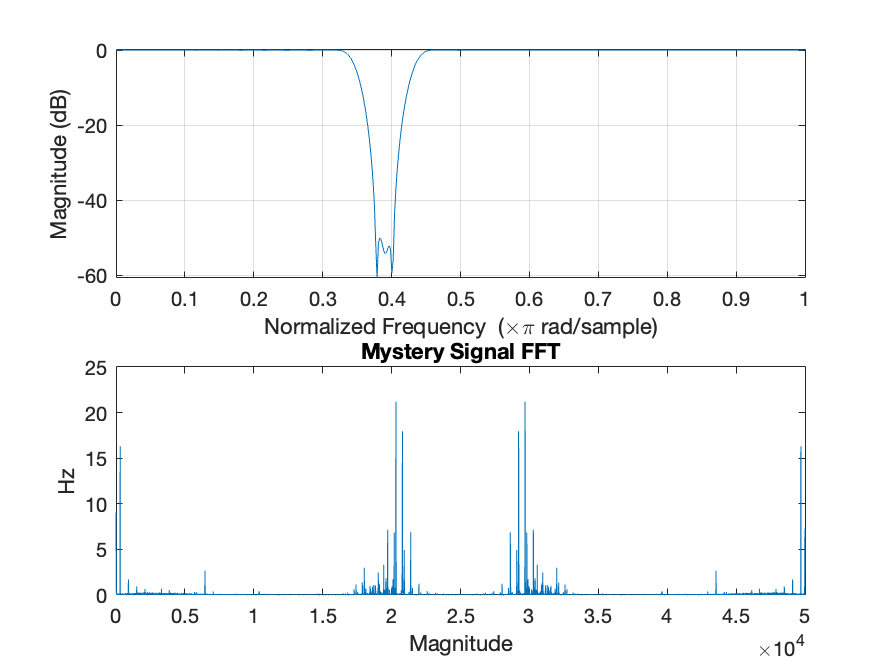

% plot filter signal
subplot(2,1,2)
plot(pf)
title('bandpass FFT');
xlabel('Magnitude');
ylabel('Hz');
plot(hf)
title('low pass FFT');
xlabel('Magnitude');
ylabel('Hz');
plot(qf)
title('highpass FFT');
xlabel('Magnitude');
ylabel('Hz');


%create the fft of mystery signal
subplot(2,1,2),plot(abs(s))
% label title and axis
title('Mystery Signal FFT');
xlabel('Magnitude');
ylabel('Hz');